# Chapter 01: Rudiments of Learning Theory

clear all; clc;

## Some loss functions

The plots below show the function $\ell$ defining a loss function via ${\rm Loss}(y,y') = \ell(y-y')$, $y,y' \in \mathbb{R}$,

- for the square loss: $\ell_{\rm sq}(z) = z^2$;

- for the absolute loss: $\ell_{\rm abs}(z) = |z|$;

- for the Huber loss with parameter $\delta > 0$: $\ell_{\rm Huber}(z) = 
\left\{ 
\matrix{
\frac{1}{2} z^2 ,& |z| \le \delta, 
\cr
\frac{1}{2} (2\delta |z| - \delta^2), & |z| > \delta.
}
\right.$ 

Definition of the Huber function

Huber = @(delta,z) ( (abs(z)<=delta).*z.^2 +...
    (abs(z) > delta).*(2*delta*abs(z)-delta^2) )/2;

Plot of the functions defining the three losses

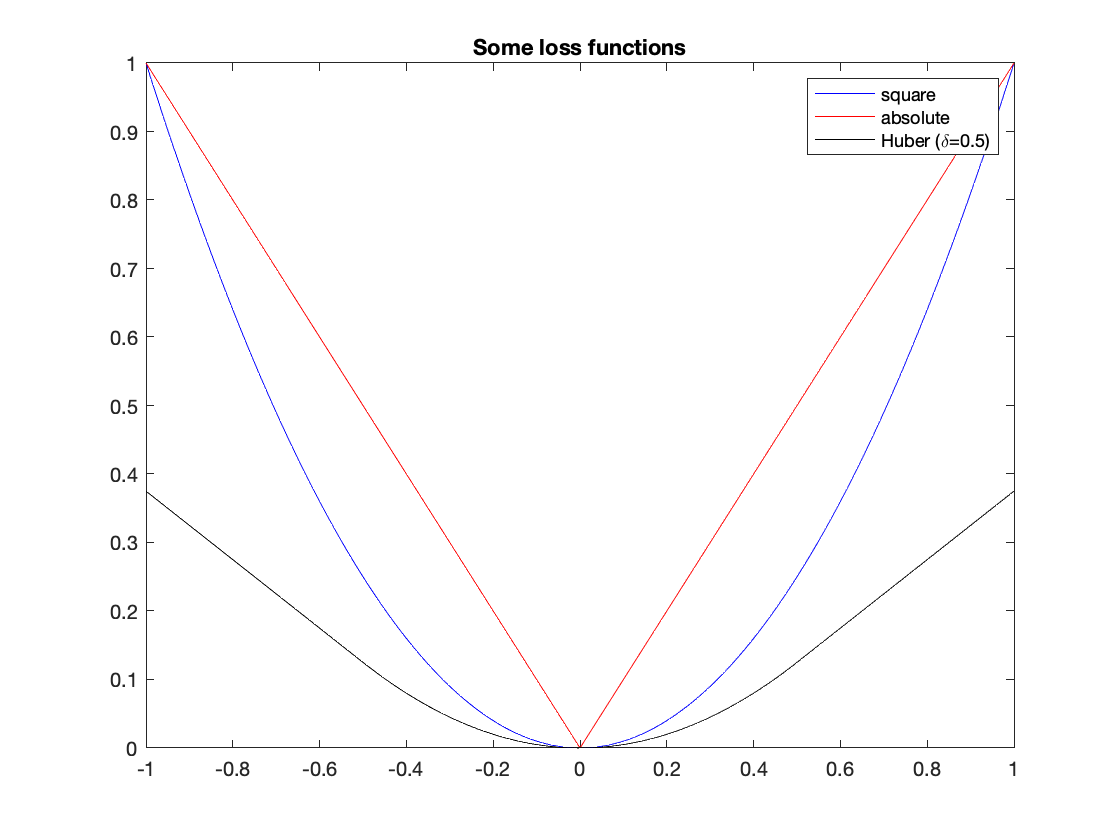

delta = 0.5;
grid = linspace(-1,1,500);
figure(1);
plot(grid,grid.^2,'b-',grid,abs(grid),'r-',grid,Huber(delta,grid),'k-')
legend('square','absolute',strcat('Huber (\delta=',num2str(delta),')'))
title('Some loss functions')

## Some empirical risk minimizations

One uses the square loss and a hypothesis class of univariate polynomials

% generate the data
m = 15;
x = [-1;sort(2*rand(m-2,1)-1);1];
y = abs(x) + randn(m,1);

Using polynomials of low degree leads to underfitting

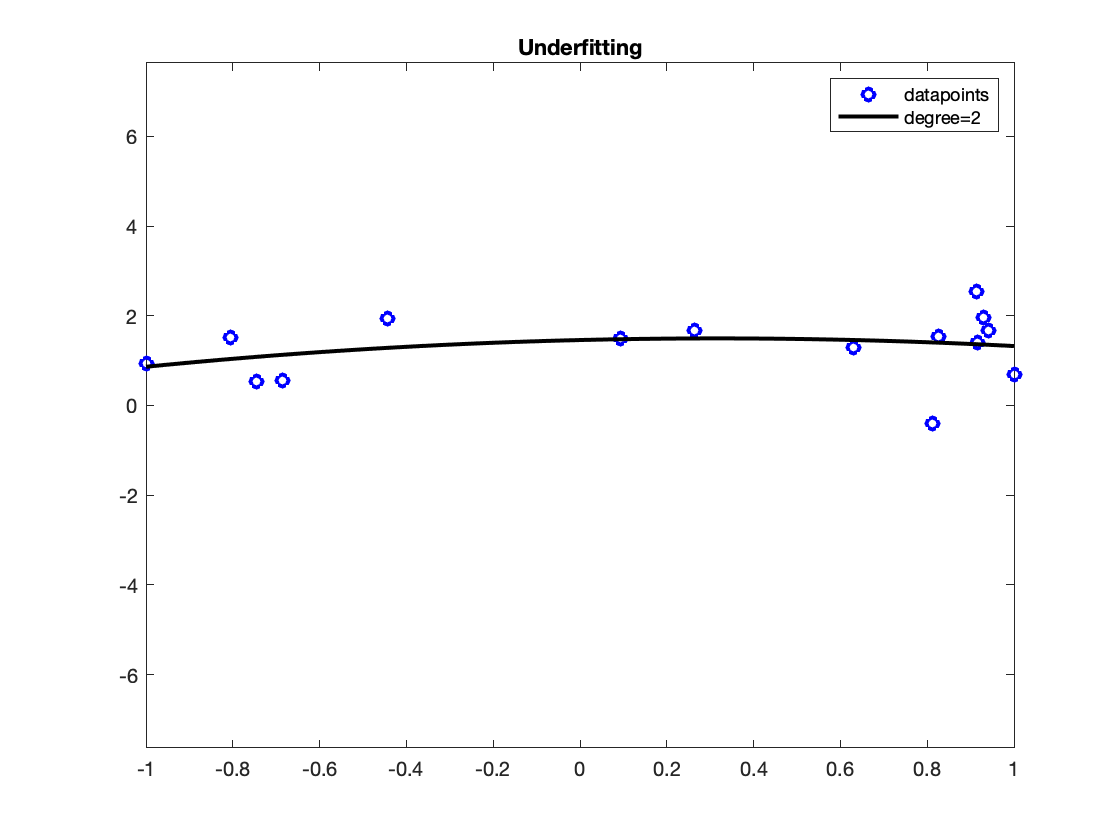

deg = 2;
p_underfit = polyfit(x,y,deg);
grid = linspace(-1,1,500)';
figure(2);
plot(x,y,'bo',grid,polyval(p_underfit,grid),'k-','LineWidth',2);
legend('datapoints',strcat('degree=',num2str(deg)));
title('Underfitting')
axis([-1 1 -3*max(y) 3*max(y)])

Using polynomials of high degree leads to overfitting

deg = 20;
p_overfit = polyfit(x,y,deg);

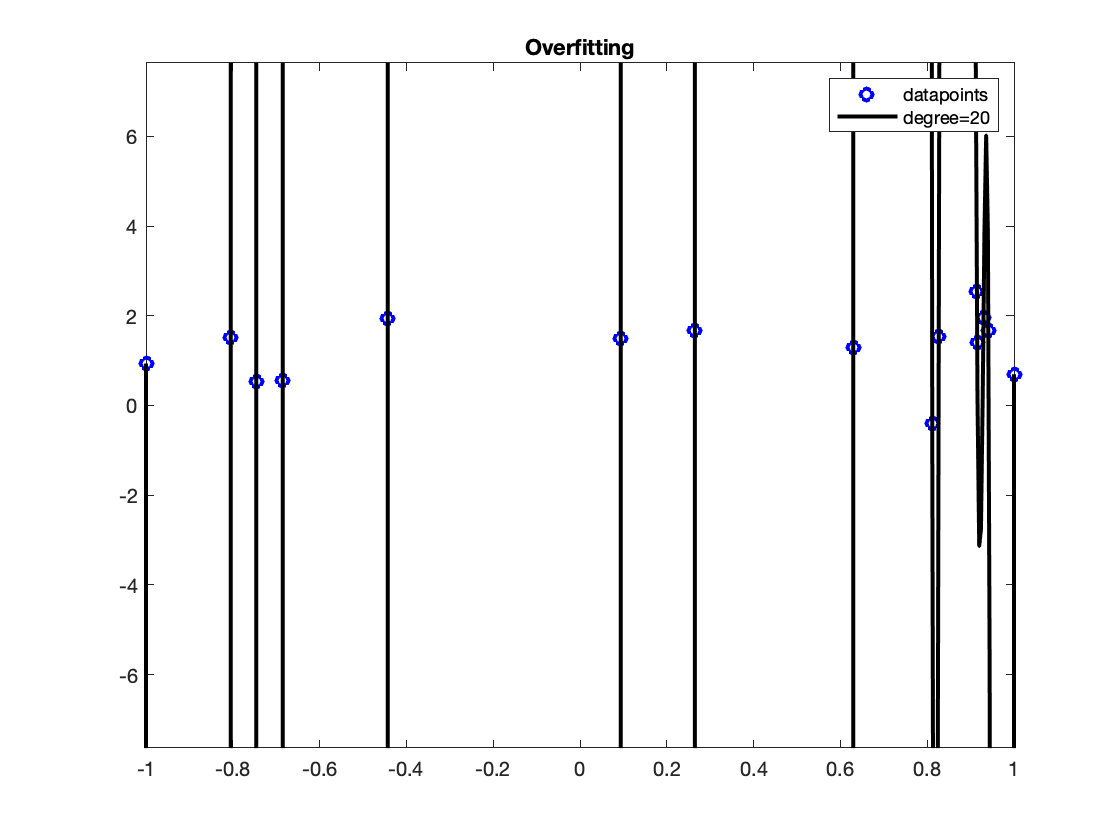

grid = linspace(-1,1,500)';
figure(3);
plot(x,y,'bo',grid,polyval(p_overfit,grid),'k-','LineWidth',2);
legend('datapoints',strcat('degree=',num2str(deg)));
title('Overfitting')
axis([-1 1 -3*max(y) 3*max(y)])